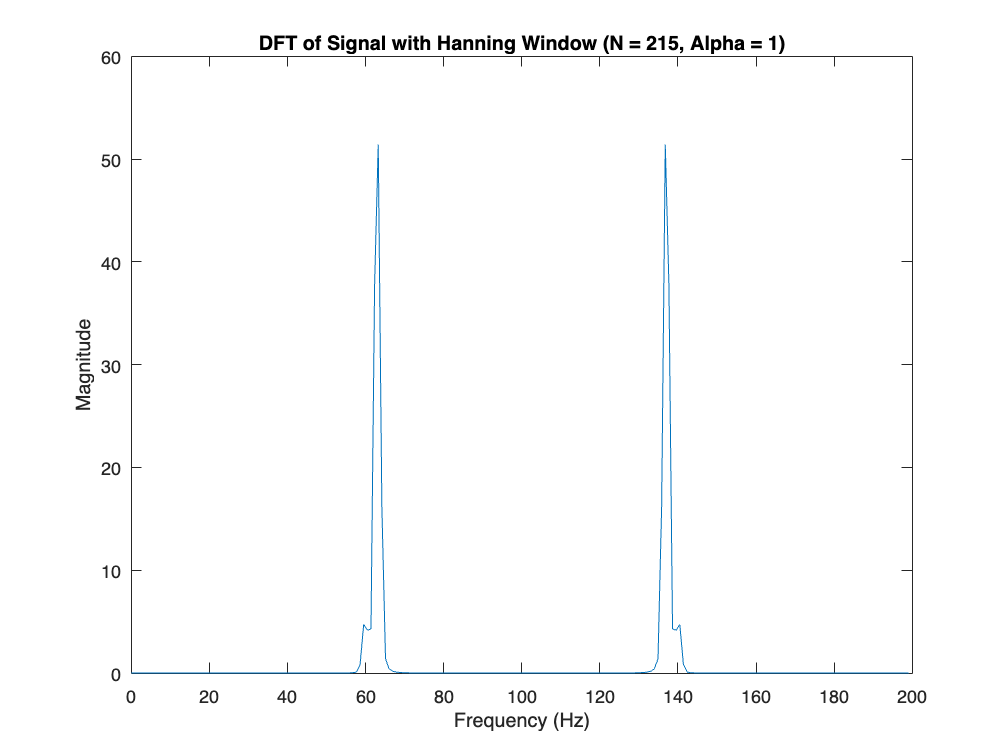

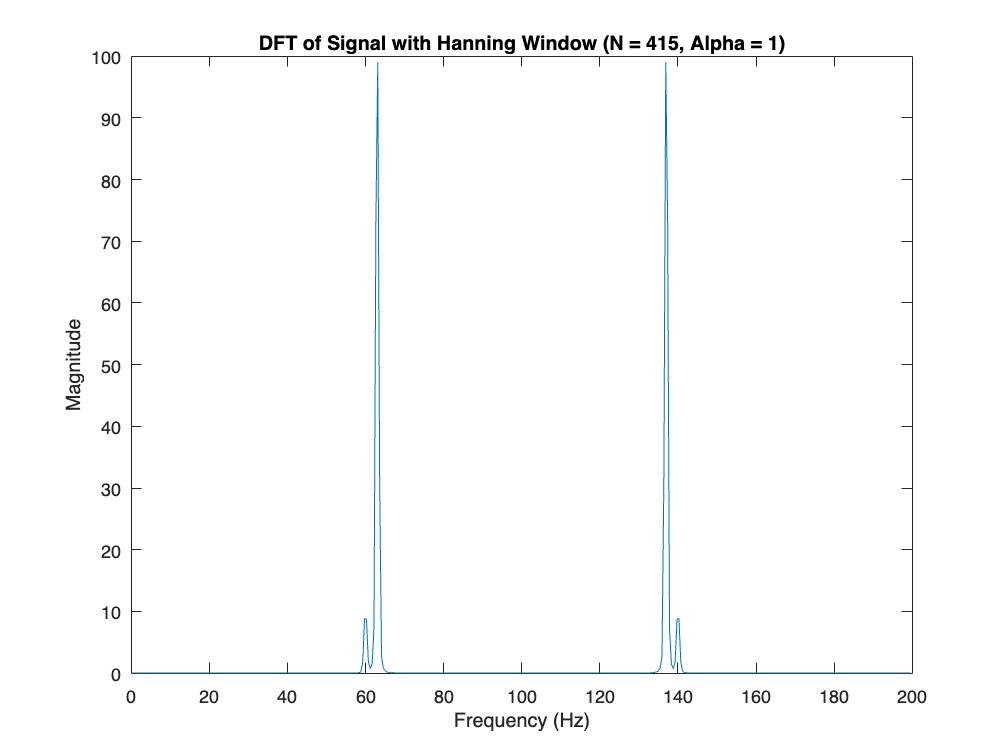

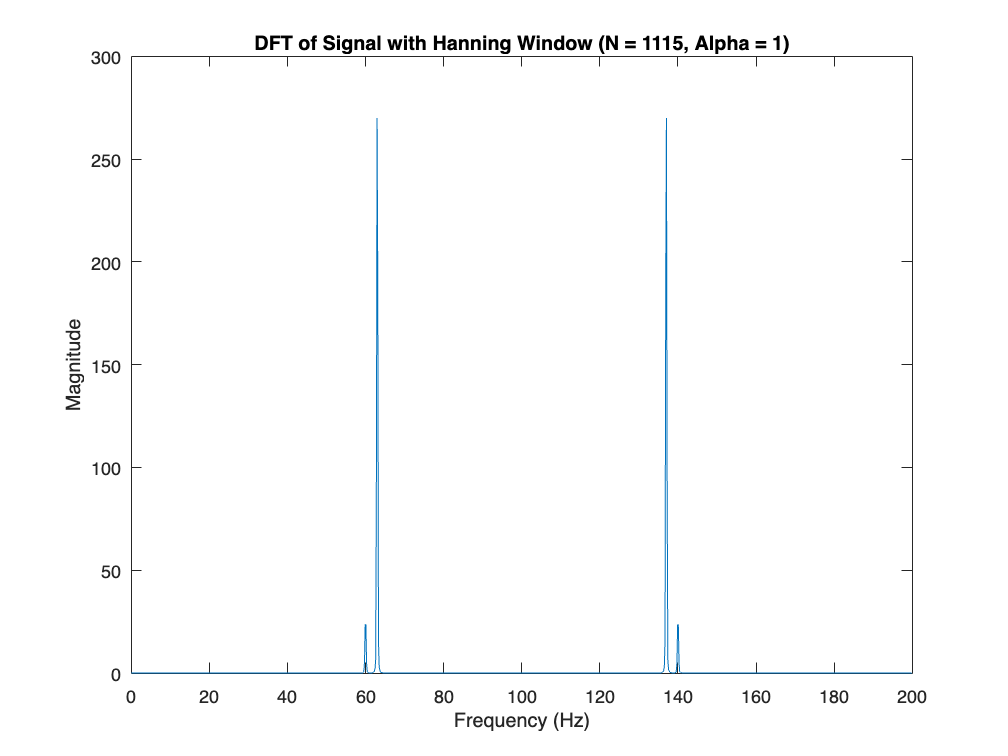

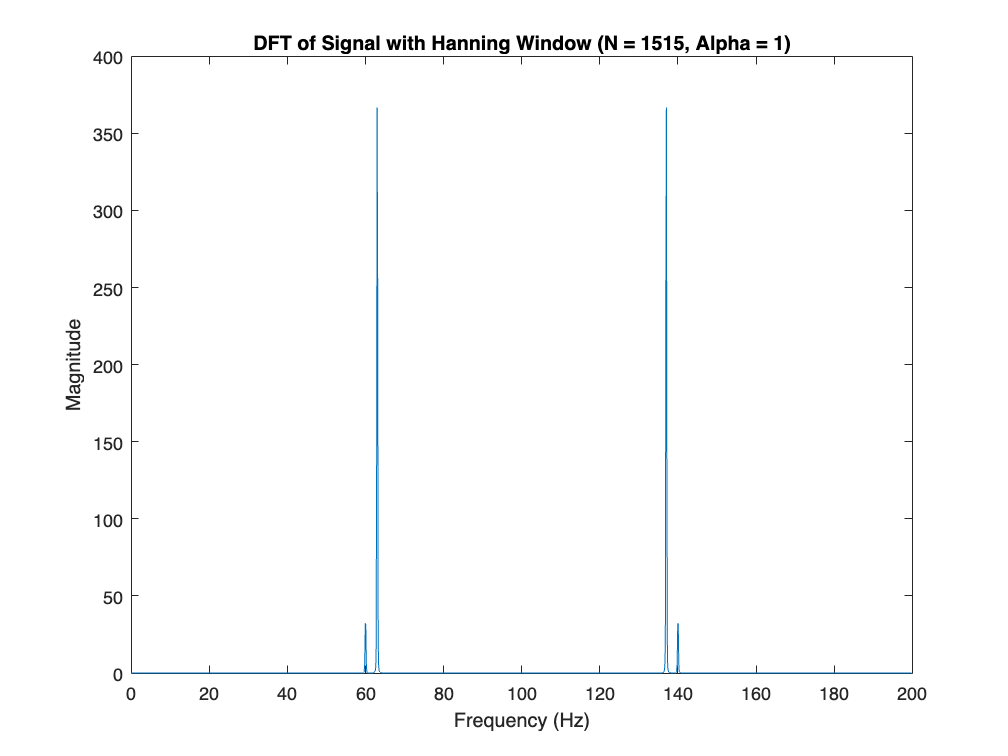

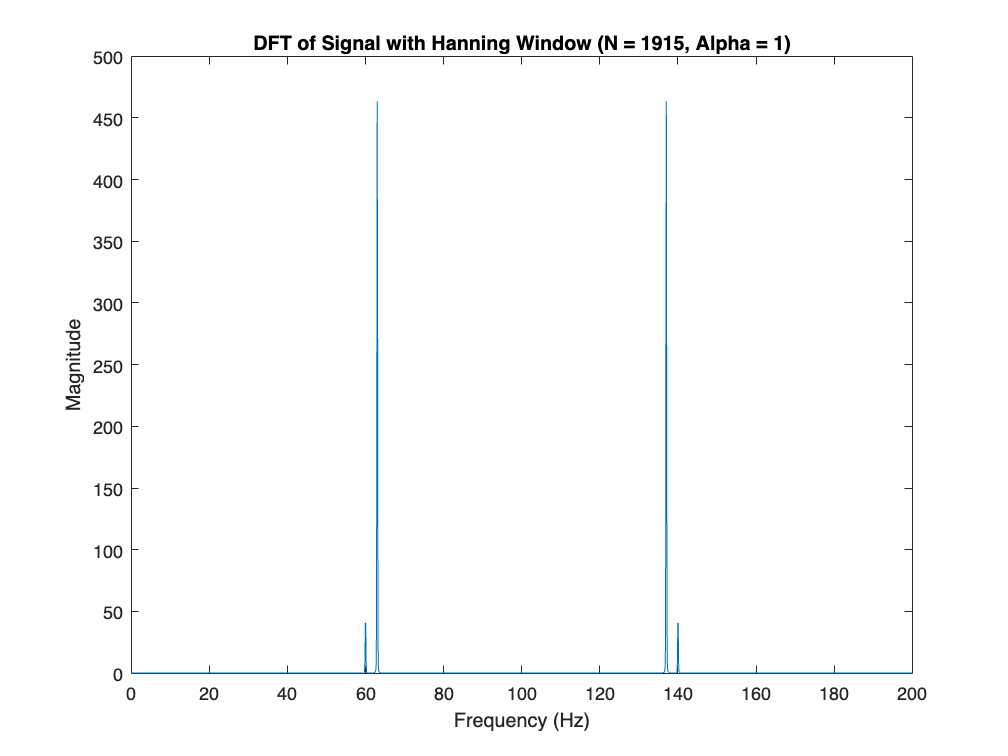

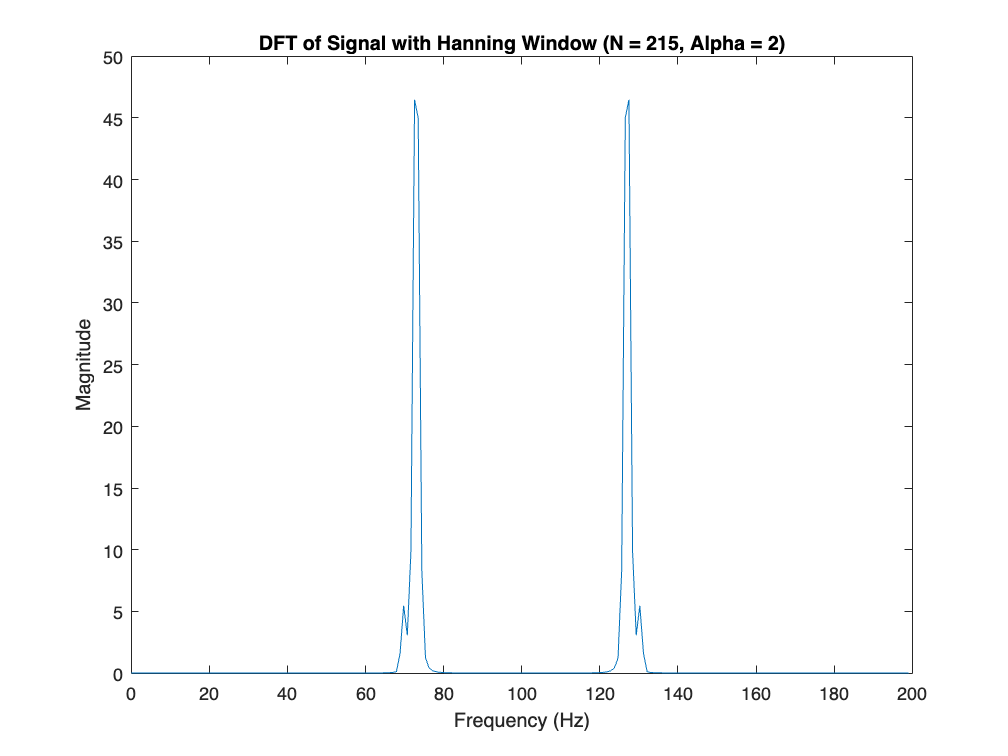

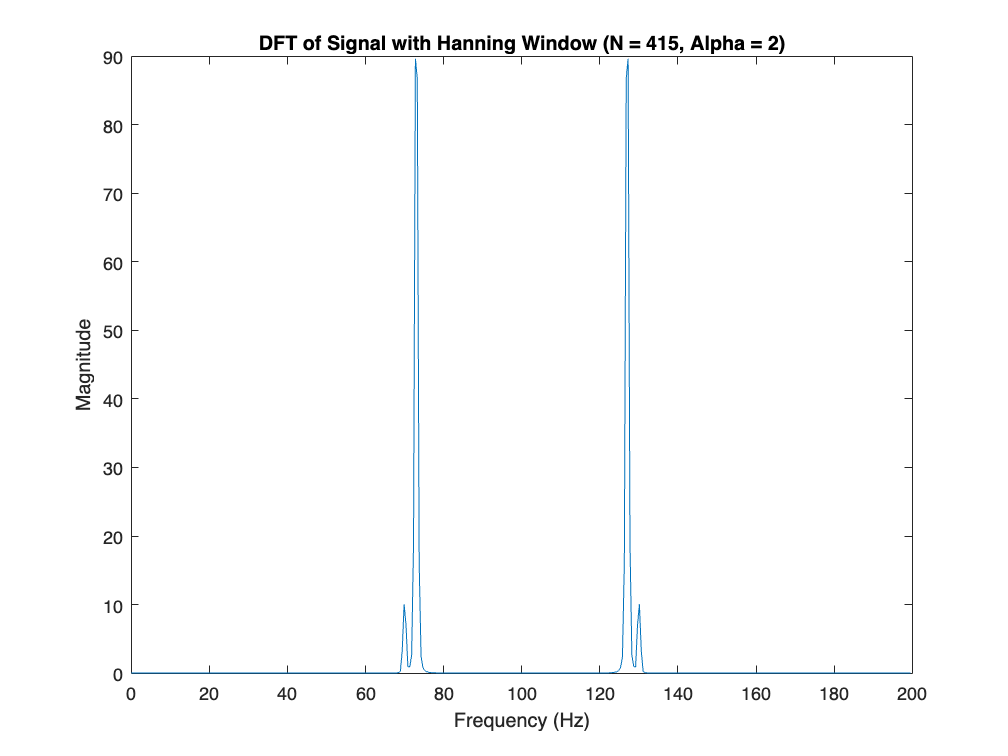

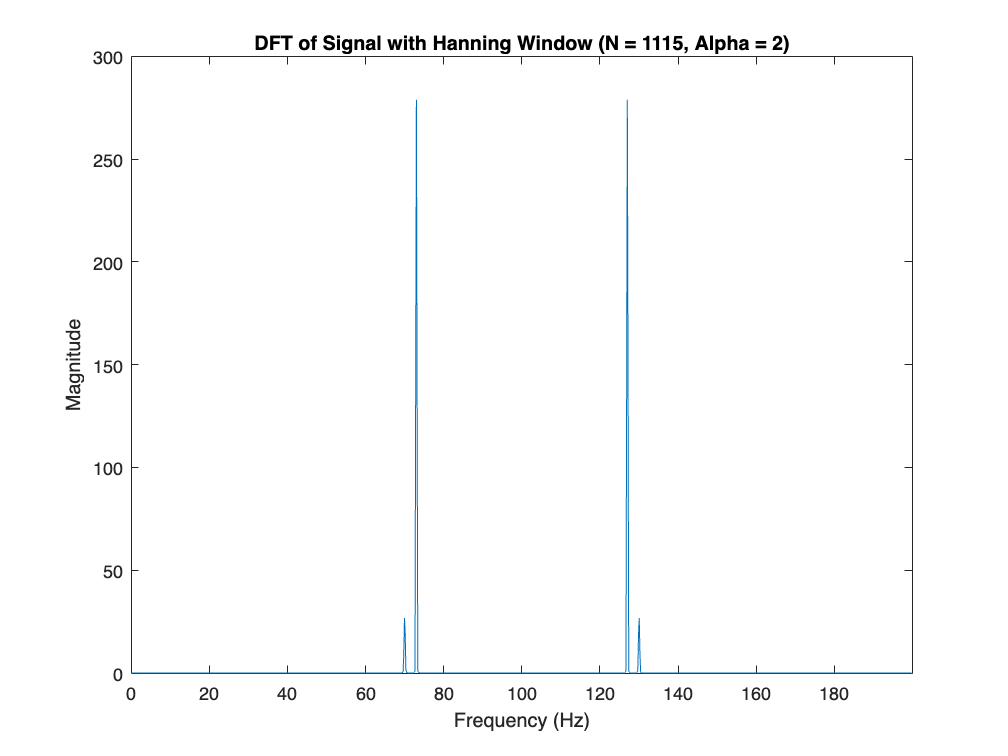

alpha_values = [1, 2, 3];
A_values = [120, 140, 160];
B_values = [126, 146, 166];
duration = 10; % Duration 
sampling_rate = 200; % Samples per second

% Create a time vector
t = 0:1/sampling_rate:duration-1/sampling_rate;

for i = 1:length(alpha_values)
    alpha = alpha_values(i);
    A = A_values(i);
    B = B_values(i);
    
    % Generate the signal
    xa =  0.1*sin(A * pi * t) + cos(B * pi * t);
    
    % Define the different numbers of samples to plot DFT
    sample_counts = [215, 415, 1115, 1515, 1915];
    
    for j = 1:length(sample_counts)
        N = sample_counts(j);
        
        % Apply the appropriate window depending on alpha
        
        window = hanning(N)';
        
        
        % Apply the window to the signal
        xa_windowed = xa(1:N) .* window;
        
        % Compute the DFT of the windowed signal
        dft = fft(xa_windowed);
        frequencies = (0:N-1) * sampling_rate / N;
        magnitude = abs(dft);
        
        % Plot the DFT for each N in a separate figure
        figure;
        plot(frequencies, magnitude);
        title(['DFT of Signal with Hanning Window (N = ', num2str(N), ', Alpha = ', num2str(alpha), ')']);
        xlabel('Frequency (Hz)');
        ylabel('Magnitude');
    end
end